Here is a $1000\times 1000$ matrix of density around 0.5%.

A = 0.6*speye(1000) + sprand(1000,1000,0.005,1/10000);

Without a preconditioner, GMRES takes a large number of iterations. 

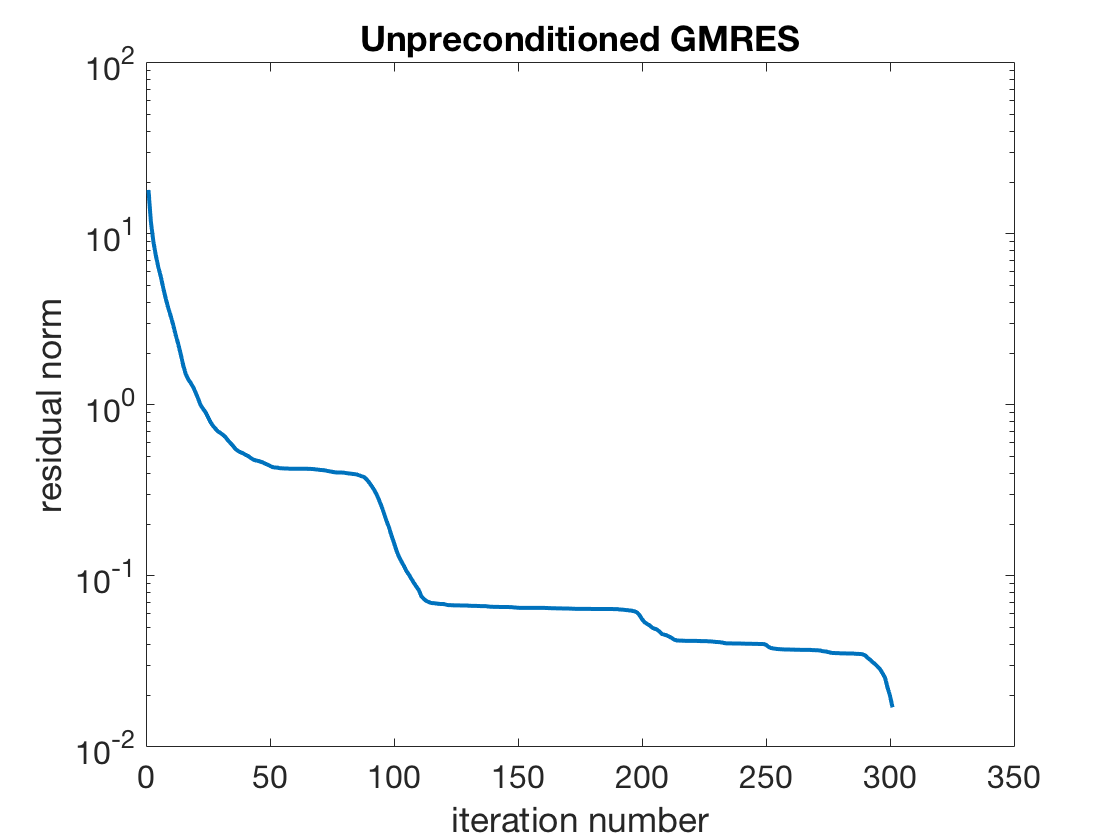

b = rand(1000,1); 
[x,~,~,~,resid_plain] = gmres(A,b,50,1e-10,6);  % restart at 50
clf, semilogy(resid_plain,'-')
xlabel('iteration number'), ylabel('residual norm')    % ignore this line
title('Unpreconditioned GMRES')   % ignore this line

This version of incomplete LU factorization simply prohibits fill-in for the factors, freezing the sparsity pattern of the approximate factors. 

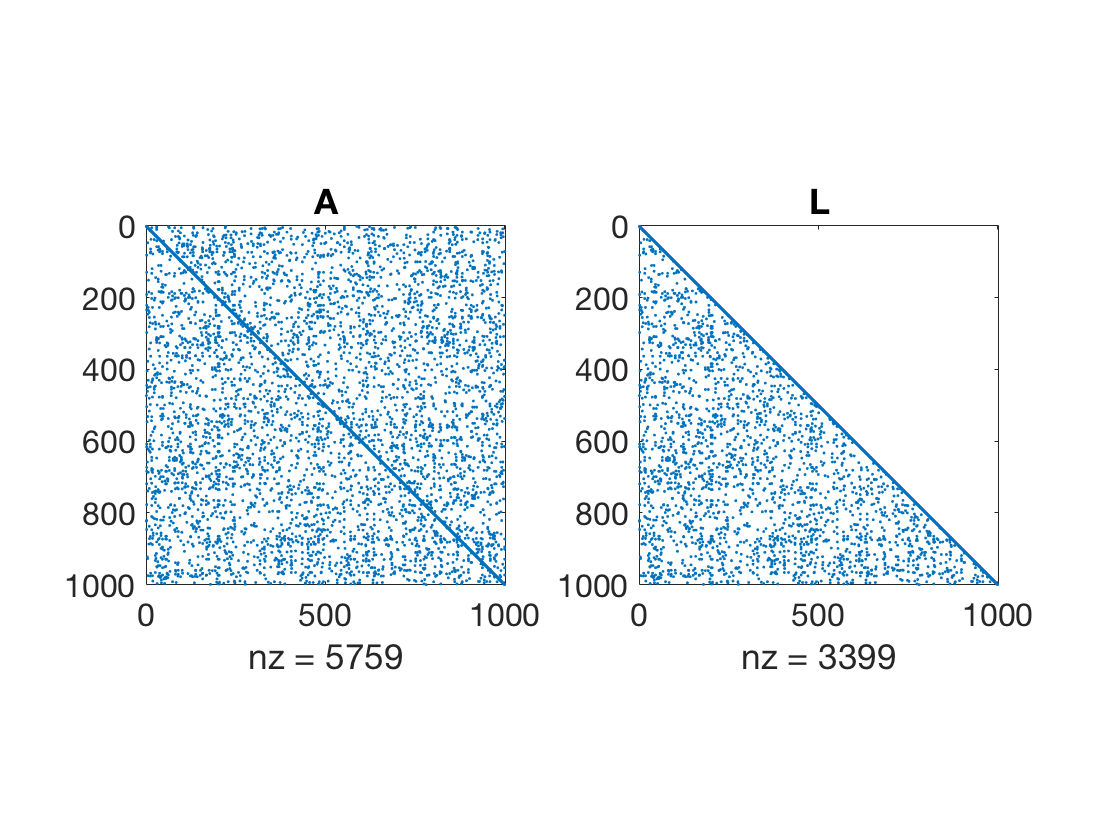

[L,U] = ilu(A);
subplot(121), spy(A)
title('A')   % ignore this line
subplot(122), spy(L)
title('L')   % ignore this line

It does *not* produce a true factorization of $\mathbf{A}$.

norm( full(A - L*U) )

ans =    1.558740741083898


The actual preconditioning matrix is $\mathbf{M}=\mathbf{L}\mathbf{U}$. However, the `gmres` function allows setting the preconditioner by giving the factors independently.

[x,~,~,~,resid_prec] = gmres(A,b,[],1e-10,300,L,U);

The preconditioning is fairly successful in this case.

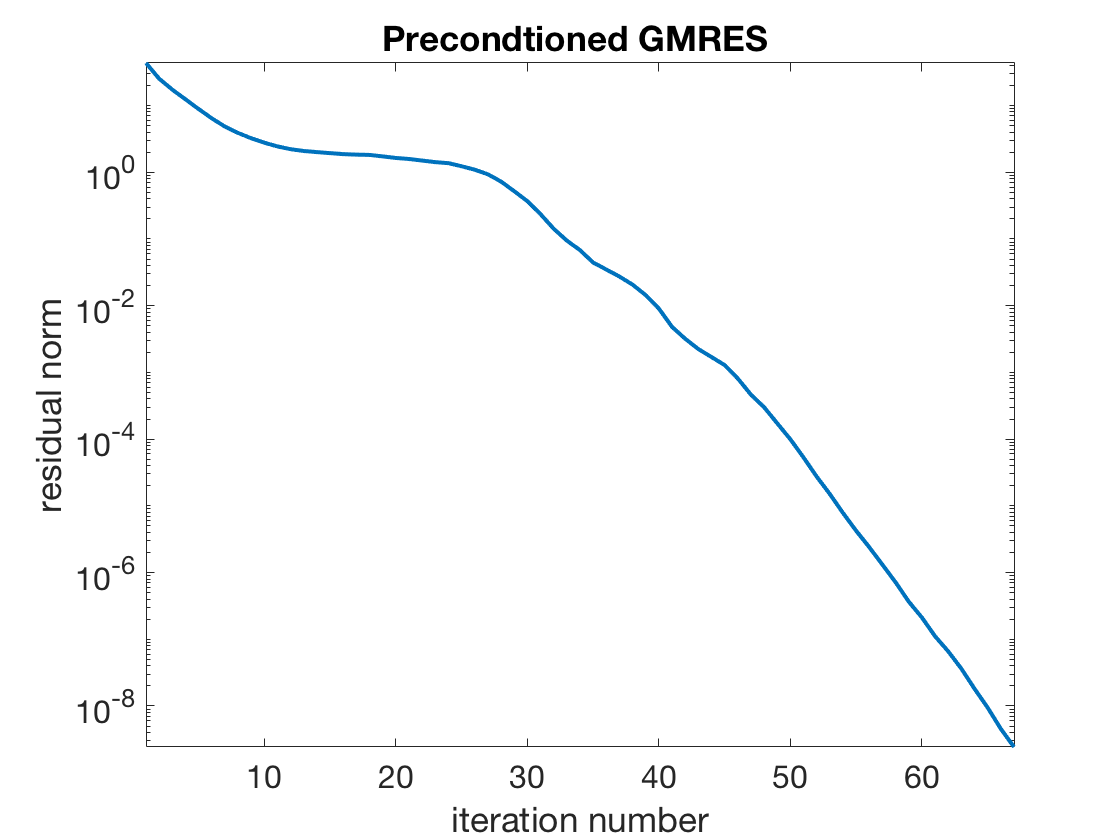

clf, semilogy(resid_prec,'-')
xlabel('iteration number'), ylabel('residual norm')    % ignore this line
title('Precondtioned GMRES ')   % ignore this line
axis tight    % ignore this line